# Day Analyze

**目的：**对比well trained与critical day之间的差别

**现象：**well train 阶段neuron和event之间的互信息更大，但之前阶段neuron之间的互信息更大，而且组合较为固定

**结论：**选取critical day应该能获得更好的预测结果

close all;clear;clc;

## Analyze rat_010_07_04(well trained)

[M1, mPFC, ratios, ~, ~, ~, eventTrain] = spikeTime2Train("data/rat_010_07_04.mat");
fprintf(['M1withSpike=%0.4f\nmPFCwithSpike=%0.4f\nM1multiSpike=%0.4f\n' ...
    'mPFCmultiSpike=%0.4f'], ratios)

M1withSpike=0.1314
mPFCwithSpike=0.0976
M1multiSpike=0.0499
mPFCmultiSpike=0.0402

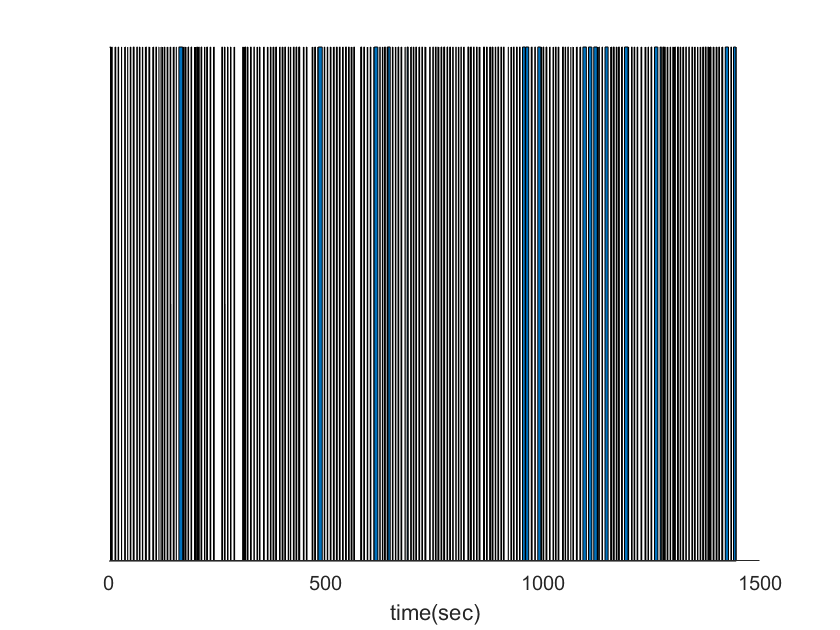

spikeLength = length(eventTrain);
figure
area(0.01:0.01:spikeLength*0.01, eventTrain)
set(gca, 'TickLength', [0 0])
set(gca, 'ytick', [])
set(gca, 'box', 'off')
set(gca, 'YColor', 'white')
xlabel("time(sec)")

event during 570.01s~910s seems continuously repeated. take for futher work.

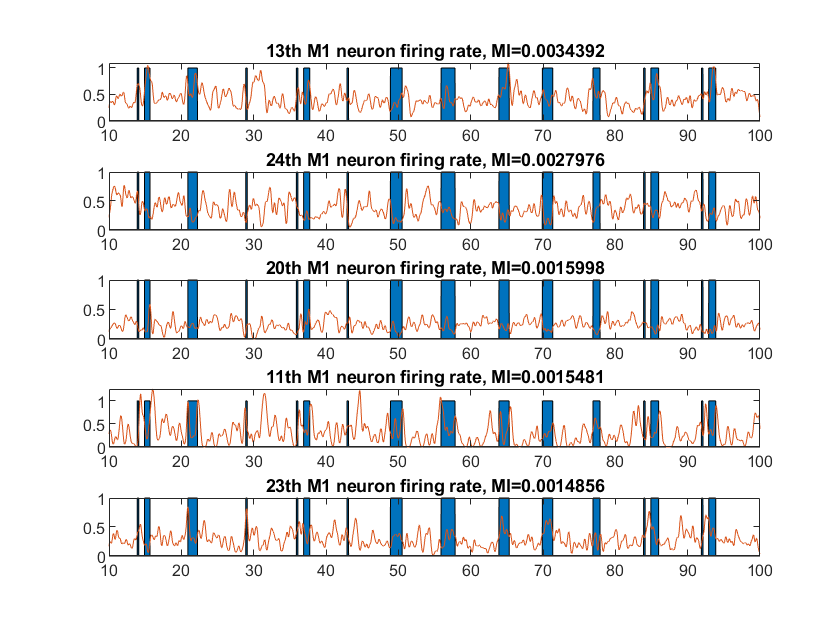

% takenBins = 57001:91000;
% spikeLength = length(takenBins);
% eventTrain = eventTrain(takenBins)';
% mPFC = mPFC(takenBins,:);
% M1 = M1(takenBins,:);
eventTrain = eventTrain';

emMI = mutualInformation(eventTrain, M1);
epMI = mutualInformation(eventTrain, mPFC);
nMI  = mutualInformation(M1, mPFC);

[mi, eM1index] = sort(emMI, 'descend');
t=10:0.01:100;
bins = 1000:10000;
figure
% subplot(6,1,1)
% area(t, eventTrain(bins))
% set(gca, 'TickLength', [0 0])
% set(gca, 'ytick', [])
% set(gca, 'box', 'off')
% set(gca, 'YColor', 'white')
% xlabel("time(sec)")
for i=1:5
  subplot(5,1,i)
  area(t, eventTrain(bins))
  hold on
  plot(t, gaussianSmooth(M1(bins, eM1index(i)), 80)*2)
  hold off
  title([num2str(eM1index(i)), 'th M1 neuron firing rate, MI=', num2str(mi(i))])
end

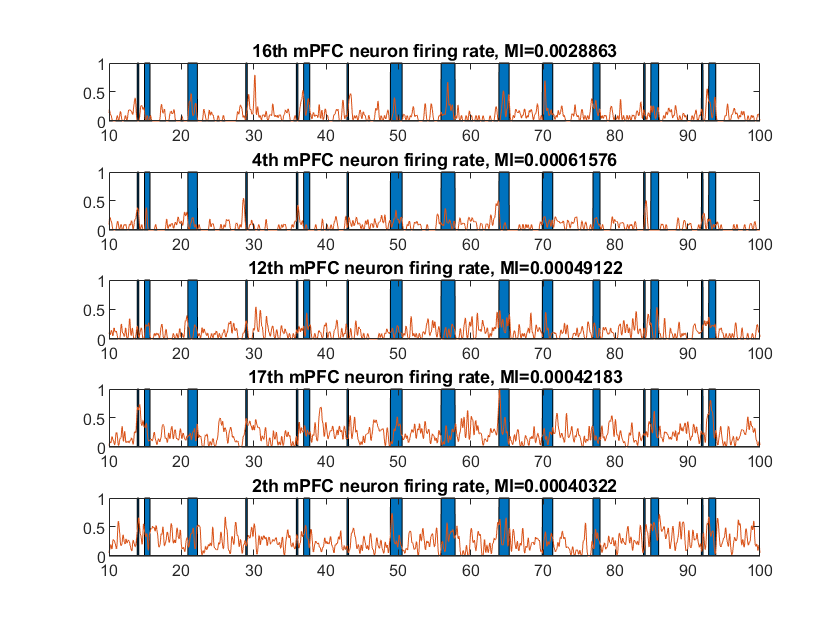

[mi, emPFCindex] = sort(epMI, 'descend');
figure
% subplot(6,1,1)
% area(t, eventTrain(bins))
% set(gca, 'TickLength', [0 0])
% set(gca, 'ytick', [])
% set(gca, 'box', 'off')
% set(gca, 'YColor', 'white')
% xlabel("time(sec)")
for i=1:5
  subplot(5,1,i)
  area(t, eventTrain(bins))
  hold on
  plot(t, gaussianSmooth(mPFC(bins, emPFCindex(i))*2, 50))
  hold off
  title([num2str(emPFCindex(i)), 'th mPFC neuron firing rate, MI=', num2str(mi(i))])
end

与event互信息前五的neuron之间的互信息

nMI(eM1index(1:5), emPFCindex(1:5))

ans = 	1.0e+-3 *

    0.0849    0.0404    0.1444    0.1181    0.0231
    0.0916    0.0023    0.0183    0.0003    0.0007
    0.0054    0.0112    0.0075    0.0112    0.0240
    0.1164    0.0038    0.0000    0.0092    0.0051
    0.0315    0.0149    0.2016    0.1605    0.1240


event-M1前五对应的五个mPFC

[mi, mPFCindex] = sort(nMI(eM1index(1:4),:), 2, 'descend');
mPFCindex(:, 1:6)

ans =     12    17    16    14    11     4
    19    16    11    14    20     8
     2     7    23    22     5     1
     6    16    20    11    10    14


以及他们的互信息

mi(:, 1:6)

ans = 	1.0e+-3 *

    0.1444    0.1181    0.0849    0.0688    0.0509    0.0404
    0.1645    0.0916    0.0812    0.0548    0.0463    0.0410
    0.0240    0.0231    0.0223    0.0180    0.0175    0.0159
    0.1529    0.1164    0.1079    0.0631    0.0431    0.0403


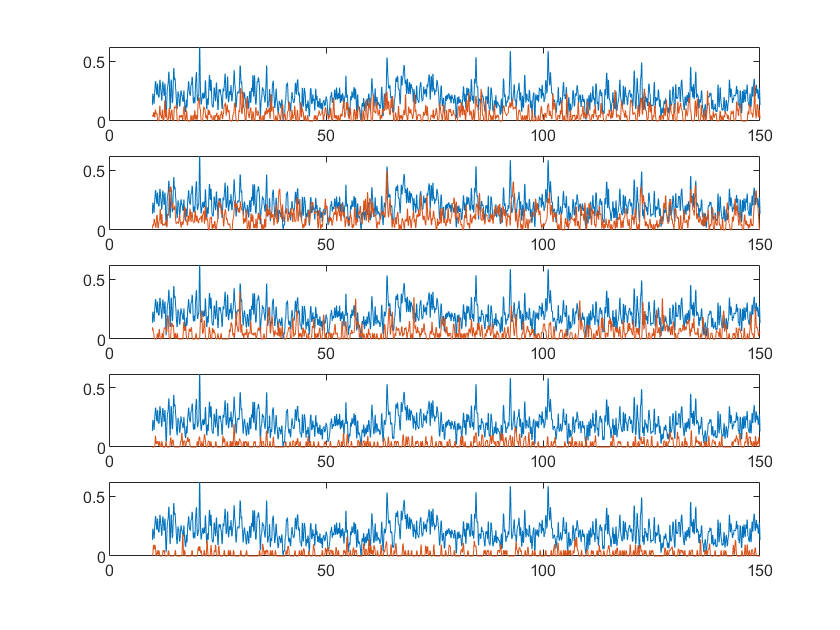

t=10:0.01:150;
bins = 1000:15000;
figure
for i=1:5
  subplot(5,1,i)
  plot(t, gaussianSmooth(M1(bins, 7), 50))
  hold on
  plot(t, gaussianSmooth(mPFC(bins, mPFCindex(1,i)), 50))
  hold off
end

## Analyze rat010_0615(critical day)

close all;clear;clc;
[M1, mPFC, ratios, ~, ~, ~, eventTrain] = spikeTime2Train("data/data_rat010_0615_event");
fprintf(['M1withSpike=%0.4f\nmPFCwithSpike=%0.4f\nM1multiSpike=%0.4f\n' ...
    'mPFCmultiSpike=%0.4f'], ratios)

M1withSpike=0.2069
mPFCwithSpike=0.1322
M1multiSpike=0.1154
mPFCmultiSpike=0.0669

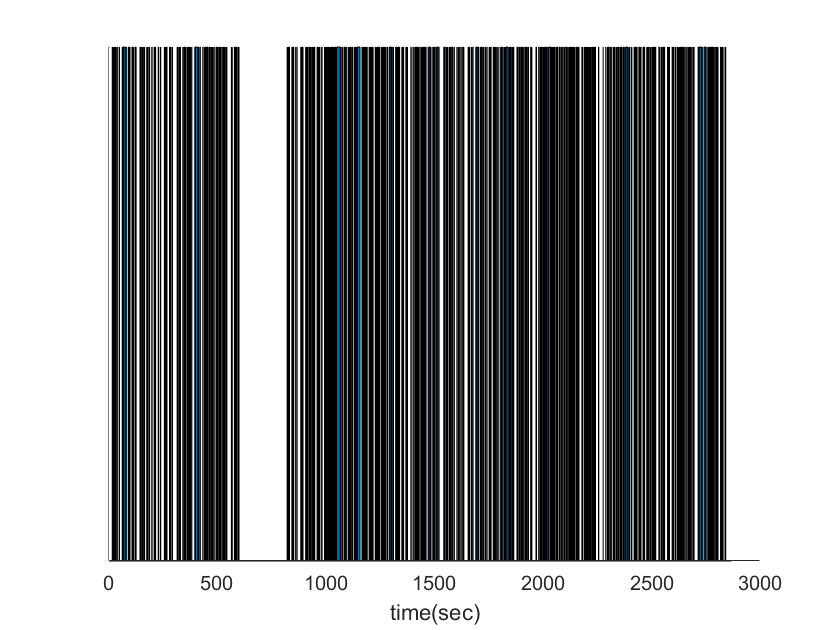

spikeLength = length(eventTrain);
figure
area(0.01:0.01:spikeLength*0.01, eventTrain)
set(gca, 'TickLength', [0 0])
set(gca, 'ytick', [])
set(gca, 'box', 'off')
set(gca, 'YColor', 'white')
xlabel("time(sec)")

event during 820.01s~1600s seems continuously repeated. take for futher work.

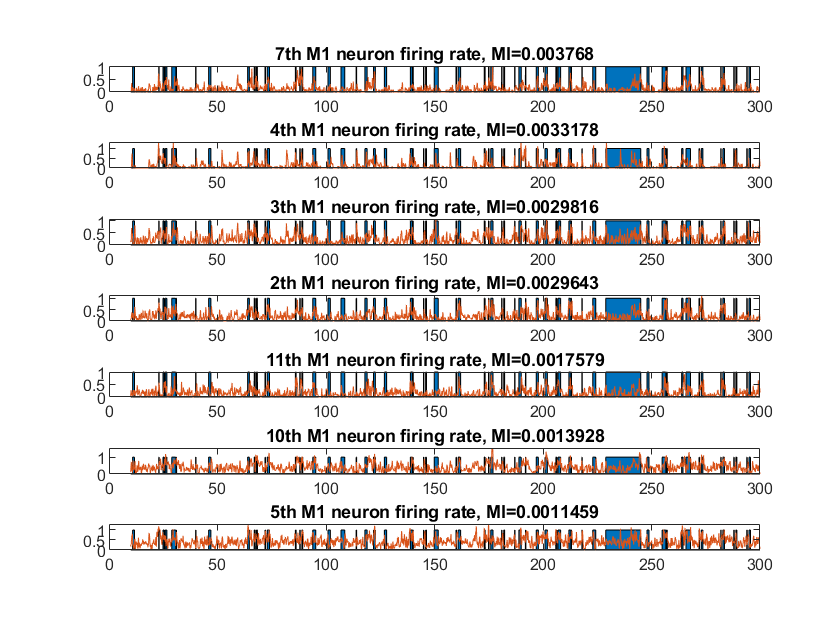

takenBins = 82001:160000;
spikeLength = length(takenBins);
eventTrain = eventTrain(takenBins)';
mPFC = mPFC(takenBins,:);
M1 = M1(takenBins,:);

emMI = mutualInformation(eventTrain, M1);
epMI = mutualInformation(eventTrain, mPFC);
nMI  = mutualInformation(M1, mPFC);

[mi, eM1index] = sort(emMI, 'descend');
t=10:0.01:300;
bins = 1000:30000;
figure
% subplot(6,1,1)
% area(t, eventTrain(bins))
% set(gca, 'TickLength', [0 0])
% set(gca, 'ytick', [])
% set(gca, 'box', 'off')
% set(gca, 'YColor', 'white')
% xlabel("time(sec)")
for i=1:7
  subplot(7,1,i)
  area(t, eventTrain(bins))
  hold on
  plot(t, gaussianSmooth(M1(bins, eM1index(i)), 50)*2)
  hold off
  title([num2str(eM1index(i)), 'th M1 neuron firing rate, MI=', num2str(mi(i))])
end

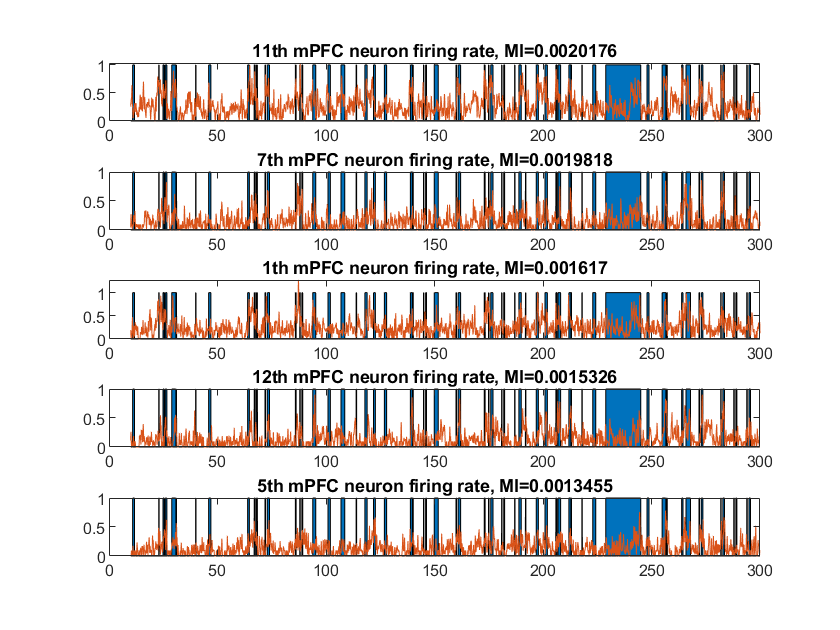

[mi, emPFCindex] = sort(epMI, 'descend');
figure
% subplot(6,1,1)
% area(t, eventTrain(bins))
% set(gca, 'TickLength', [0 0])
% set(gca, 'ytick', [])
% set(gca, 'box', 'off')
% set(gca, 'YColor', 'white')
% xlabel("time(sec)")
for i=1:5
  subplot(5,1,i)
  area(t, eventTrain(bins))
  hold on
  plot(t, gaussianSmooth(mPFC(bins, emPFCindex(i)), 50)*2)
  hold off
  title([num2str(emPFCindex(i)), 'th mPFC neuron firing rate, MI=', num2str(mi(i))])
end

与event互信息前五的neuron之间的互信息

nMI(eM1index(1:5), emPFCindex(1:5))

ans =     0.0008    0.0074    0.0018    0.0012    0.0037
    0.0008    0.0012    0.0013    0.0002    0.0005
    0.0008    0.0039    0.0015    0.0005    0.0017
    0.0010    0.0053    0.0016    0.0010    0.0026
    0.0008    0.0034    0.0012    0.0008    0.0018


event-M1前五对应的五个mPFC

[mi, mPFCindex] = sort(nMI(eM1index(1:5),:), 2, 'descend');
disp(num2str(mPFCindex(:, 1:8)))

7   8   5   6  13   1  12  10
1   7  11   8   5   2  12   6
7   8   5   1   6  13  11   3
7   8   5   1   6  13  11  12
7   5   8   6   1  13  11  12


以及他们的互信息

mi(:, 1:8)

ans =     0.0074    0.0041    0.0037    0.0030    0.0022    0.0018    0.0012    0.0009
    0.0013    0.0012    0.0008    0.0007    0.0005    0.0003    0.0002    0.0002
    0.0039    0.0028    0.0017    0.0015    0.0011    0.0009    0.0008    0.0006
    0.0053    0.0027    0.0026    0.0016    0.0016    0.0014    0.0010    0.0010
    0.0034    0.0018    0.0013    0.0012    0.0012    0.0011    0.0008    0.0008


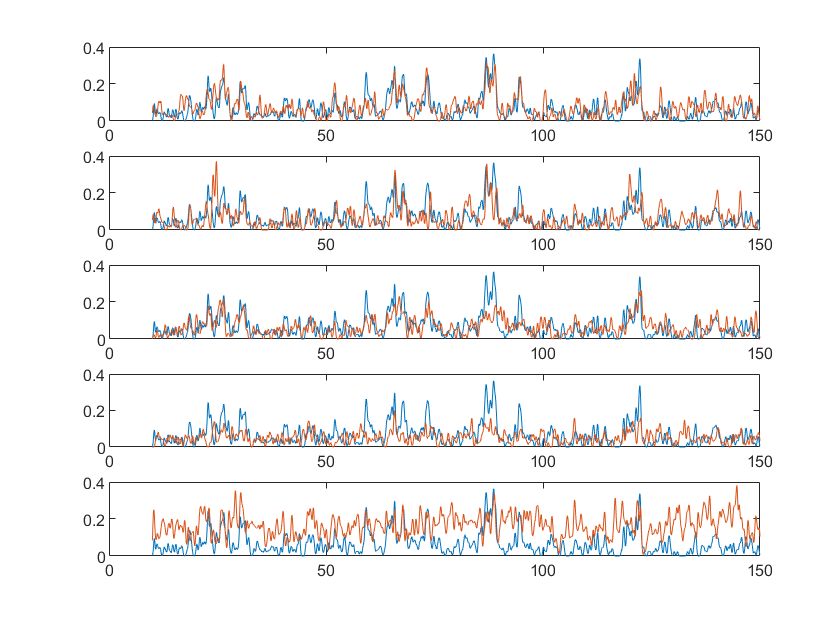

t=10:0.01:150;
bins = 1000:15000;
figure
for i=1:5
  subplot(5,1,i)
  plot(t, gaussianSmooth(M1(bins, 7), 100))
  hold on
  plot(t, gaussianSmooth(mPFC(bins, mPFCindex(1,i)), 100))
  hold off
end

可以看出在critical day的mPFC与M1的联系似乎更为紧密，因此选取其中部分数据来跑模型

依然选取其中mutual information比较大的来做数据集，mPFC的数量是自己估计的

M1neurons   = [7 11 17];
mPFCneurons = [5 6 7 8 13];
M1spike = M1(:, M1neurons);
mPFCspike = mPFC(:, mPFCneurons);
% save("data/data_rat010_0615_spike_train_selected.mat", "M1spike", "mPFCspike", "eventTrain")